# Finding the variance (within bin), pooled over bins, neurons, sessions, and mice

For a particular bin, neuron, session, mouse:

d = SessManager.load_special('Mouse2022', 'events_transients');

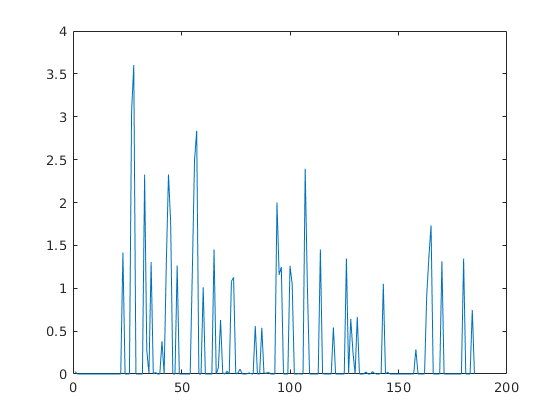

[X, ks] = d.get_dataset;
neuron_idx = 300;
bin_idx = 10;
trial_values = X(ks==bin_idx,neuron_idx);
figure;
plot(trial_values);

std_value = std(trial_values)

std_value = 0.6646

## Aggregated over all

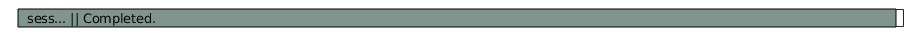

sm = SessManager;

tot_count = 0;
tot_sum = 0;
tot_sum_sq = 0;

progressbar('sess...');
for i = 1:sm.num_usable
    d = sm.cons_usable(i);
    [X, ks] = d.get_dataset;
    for k = 1:40
        ks_filt = ks == k;
        for n = 1:size(X,2)
            val = std(X(ks_filt,n));
            
            tot_count = tot_count + 1;
            tot_sum = tot_sum + val;
            tot_sum_sq = tot_sum_sq + val.^2;
        end
    end
    progressbar(i/sm.num_usable);
end

tot_mean = tot_sum ./ tot_count

tot_mean = 0.7263

tot_mean_sq = tot_sum_sq ./ tot_count;

tot_var = tot_mean_sq - tot_mean.^2;
tot_std = sqrt(tot_var)

tot_std = 0.6117

## Some kind of "SNR", aggregated

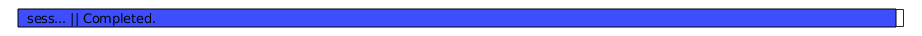

sm = SessManager;

tot_count = 0;
tot_sum = 0;
tot_sum_sq = 0;

progressbar('sess...');
for i = 1:sm.num_usable
    d = sm.cons_usable(i);
    [X, ks] = d.get_dataset;
    for n = 1:size(X,2)
        mean_resp_per_bin = zeros(40,1);
        var_per_bin = zeros(40,1);
        for k = 1:40
            ks_filt = ks == k;

            trial_vals = X(ks_filt,n);
            mean_resp_per_bin(k) = mean(trial_vals);
            var_per_bin(k) = var(trial_values);
        end
        var_mean = var(mean_resp_per_bin);
        mean_var = mean(var_per_bin);
        vm_by_mv = var_mean ./ mean_var;
        
        tot_count = tot_count + 1;
        tot_sum = tot_sum + vm_by_mv;
        tot_sum_sq = tot_sum_sq + vm_by_mv.^2;
    end
    progressbar(i/sm.num_usable);
end

tot_mean = tot_sum ./ tot_count

tot_mean = 0.8782

tot_mean_sq = tot_sum_sq ./ tot_count;

tot_var = tot_mean_sq - tot_mean.^2;
tot_std = sqrt(tot_var)

tot_std = 0.9971

tot_sem = tot_std ./ sqrt(tot_count)

tot_sem = 0.0060